**Visualize systems of linear equations**

This shows three planes which intersect at a point, by solving the system of their equations we obtain a solution set which points the coordinate of the intersection of the planes.

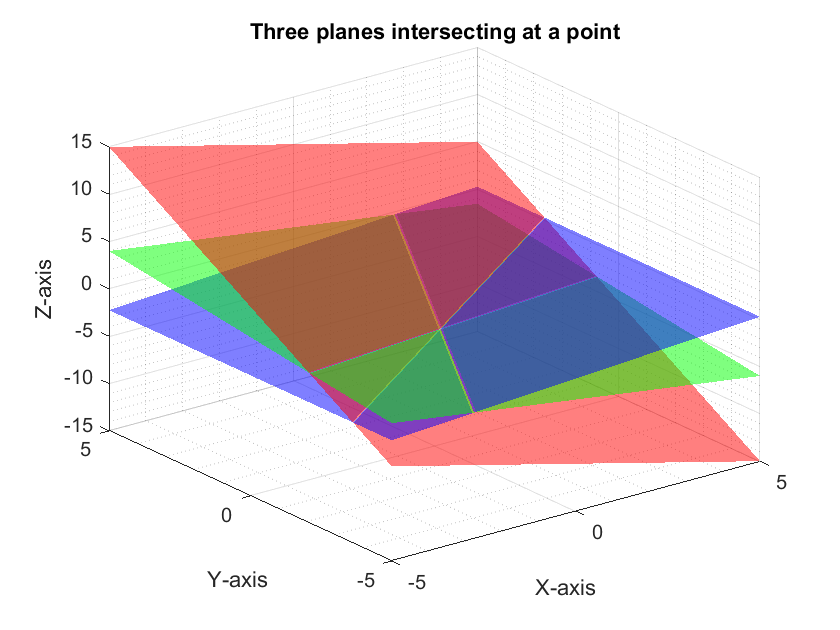

syms x y z
z1 = -x + 2*y; 
figure1 = figure;
axes1 = axes(figure1);
plane1 = fsurf(axes1,z1);
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("Three planes intersecting at a point");
plane1.MeshDensity = 50;
plane1.FaceAlpha = 0.5; % Define opacity
grid on; grid minor;
set(plane1,'FaceColor',[1 0 0]) % Sets the color to red
plane1.EdgeColor = 'none';
hold on

z2 = (1/4)*y - 1;
plane2 = fsurf(z2);
plane2.MeshDensity = 50;
plane2.FaceAlpha = 0.5; % Define opacity
set(plane2,'FaceColor','blue') % Sets the color to red
plane2.EdgeColor = 'none';

z2 = -1 - (5/9)*x + (4/9)*y;
plane2 = fsurf(z2);
plane2.MeshDensity = 50;
plane2.FaceAlpha = 0.5; % Define opacity
set(plane2,'FaceColor','green') % Sets the color to red
plane2.EdgeColor = 'none';

## Solve systems of linear equations

% Define the symbolic variables
syms x y

% Define the system of linear equations
f = 2*x + y == 5

$$f = 2\,x+y=5$$

g = x - y == 1

$$g = x-y=1$$

eqns = [f, g];

% Solve the system of linear equations
sol = solve(eqns, [x, y]);

sol.x

$$ans = 2$$

sol.y

$$ans = 1$$

## Reduced row echelon forms

A = [1 -5 4 0 0;0 1 0 1 0;0 0 3 0 0;0 0 0 2 0];

% The reduced row echelon form
reduced_A = rref(A)

reduced_A =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0



mat_B = [1 -3 5;-3 9 7]

mat_B =      1    -3     5
    -3     9     7


reduced_B = rref(mat_B)

reduced_B =      1    -3     0
     0     0     1



mat_C = [1 0 0 0 0 -1 60;1 -1 0 0 0 0 70;0 1 -1 0 0 0 -100;
    0 0 1 -1 0 0 90;0 0 0 1 -1 0 -80;0 0 0 0 1 -1 80]

mat_C =      1     0     0     0     0    -1    60
     1    -1     0     0     0     0    70
     0     1    -1     0     0     0  -100
     0     0     1    -1     0     0    90
     0     0     0     1    -1     0   -80
     0     0     0     0     1    -1    80


reduced_C = rref(mat_C)

reduced_C =      1     0     0     0     0    -1    60
     0     1     0     0     0    -1   -10
     0     0     1     0     0    -1    90
     0     0     0     1     0    -1     0
     0     0     0     0     1    -1    80
     0     0     0     0     0     0     0



mat_D = [110 130 295;4 3 9;20 18 48;2 5 8];
reduced_D = rref(mat_D)

reduced_D =     1.0000         0    1.5000
         0    1.0000    1.0000
         0         0         0
         0         0         0



flexibility_Matrix = [0.013 0.005 .002 .001;
    .005 .01 .004 .002;.002 .004 .01 .005;.001 .002 .005 .013]

flexibility_Matrix =     0.0130    0.0050    0.0020    0.0010
    0.0050    0.0100    0.0040    0.0020
    0.0020    0.0040    0.0100    0.0050
    0.0010    0.0020    0.0050    0.0130



y = [0.07; .12 ;.16 ;.12]

y =     0.0700
    0.1200
    0.1600
    0.1200



force = inv(flexibility_Matrix)*y

force =     0.9524
    6.1905
   11.4286
    3.8095
